# Spectrahedral Shadow

In CORA, spectrahedral shadows are instantiated by 

% SpS = spectraShadow(A,c,G);

where `A` is the horizontal concatenation of the coefficient matrices, `c` is the center vector, and `G` is the generator matrix.

Alternatively, a spectrahedral shadow can be instantiated as

% SpS = spectraShadow(E);

where `E` is a `1x2` cell array, where the first element is a matrix A that is the concatenation of the coefficient matrices, and the second element is a matrix `B` that is the concatenation of the additional coefficient matrices.

Example:

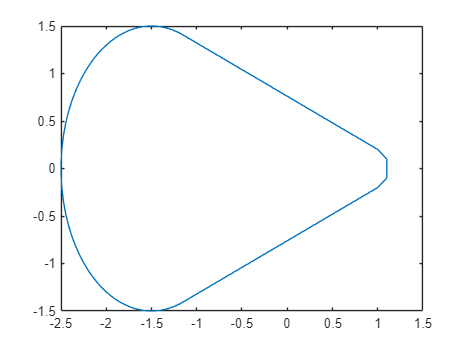

% init figure
figure;

% create two simple spectrahedral shadows
% an ellipsoid, using the first type of instantiation
A0 = eye(3);
A1 = [0 1 0; 1 0 0; 0 0 0];
A2 = [0 0 1; 0 0 0; 1 0 0];
A = [A0 A1 A2];
c = [-1.5;0];
G = [1 0;0 1.5];

SpS_ellipsoid = spectraShadow(A,c,G);

% a small zonotope, using the second type of instantiation
A0 = diag([-19 1 11 21 1 -9]);
A1 = diag([10 10 0 -10 -10 0]);
A2 = (10/3)*diag([1 -1 2 -1 1 -2]);
A = [A0 A1 A2];

B = 0.5774*diag([-1 1 1 1 -1 -1]);

ESumRep = {A, B};

SpS_zonotope = spectraShadow(ESumRep);

% we can construct more complicated sets
% based on the two above, such as the
% convex hull of the two previous spectrahedral shadows
SpS = convHull(SpS_ellipsoid, SpS_zonotope);

% plot spectraShadow
plot(SpS);

For more information, type

help spectraShadow

  spectraShadow - object constructor for spectraShadow objects
 
  Description:
     This class represents spectrahedral shadow objects defined as
     SpS = {Gx+c|A0 + x1*A1 + ... + xm*Am >= 0}
       (projection representation)
     or, equivalently,
     SpS = {y|\exists z, A0 + y1*B1 + ... + ym*Bm + z1*C1 + ... + zl*Cl>=0}
       (existential sum representation)
     where the Ai, Bi, Ci are all real, symmetric matrices, and the ">=0"
     means that the preceding matrix is positive semi-definite.
 
 
  Syntax:
     SpS = spectraShadow(A)
     SpS = spectraShadow(A,c)
     SpS = spectraShadow(A,c,G)
     SpS = spectraShadow(ESumRep)
 
  Inputs:
     A - coefficient matrices, i.e., A = [A0 A1 ... Am]
     c - center vector
     G - generator matrix
     ESumRep - Cell array with two elements, containing the existential sum
        representation of the spectrahedral shadow, i.e.,
  